# Taller 1, punto 10: Adaline sobre las particiones de Iris

A) setosa vs resto B) versicolor vs virginica. Salida en [0,1], umbral 0.5

clear; close all; clc
load iris_splits.mat

## Parametros

umbral = 0.5; salida = [0 1]; error_min = 1e-3; max_epocas = 500; semilla = 1;
alphas = [0.001 0.005 0.01 0.05 0.1];
problemas = {'A: setosa vs resto', 'B: versicolor vs virginica'};

## Entrenamiento

R = table();
for pr = 1:2
    for k = 1:4
        if pr == 1
            Xtr = S(k).Xtr; Xte = S(k).Xte;
            dtr = double(S(k).ytr == 1);  dte = double(S(k).yte == 1);
        else
            mtr = S(k).ytr ~= 1; mte = S(k).yte ~= 1;
            Xtr = S(k).Xtr(mtr,:); Xte = S(k).Xte(mte,:);
            dtr = double(S(k).ytr(mtr) == 2);  dte = double(S(k).yte(mte) == 2);
        end
        mn = min(Xtr); mx = max(Xtr);
        Xtr = (Xtr - mn) ./ (mx - mn);  Xte = (Xte - mn) ./ (mx - mn);
        for a = alphas
            [w, b, ep, EC] = adaline(Xtr, dtr, a, error_min, max_epocas, semilla);
            acc_tr = 100*mean(predecir(Xtr, w, b, umbral, salida) == dtr);
            acc_te = 100*mean(predecir(Xte, w, b, umbral, salida) == dte);
            R = [R; table(problemas(pr), k, {sprintf('%d-%d', 100*S(k).p, 100-100*S(k).p)}, a, ep, EC(end), acc_tr, acc_te, ...
                 'VariableNames', {'Problema','k','Particion','Alpha','Epocas','EC_final','Exact_train','Exact_test'})];
            if k == 1 && a == 0.01, curva{pr} = EC; end
        end
    end
end
R

R = 40×8 table
           Problema           k    Particion    Alpha    Epocas    EC_final    Exact_train    Exact_test
    ______________________    _    _________    _____    ______    ________    ___________    __________

    {'A: setosa vs resto'}    1    {'60-40'}    0.001     500      0.95925         100           100    
    {'A: setosa vs resto'}    1    {'60-40'}    0.005     500      0.94532         100           100    
    {'A: setosa vs resto'}    1    {'60-40'}     0.01     500      0.94854         100           100    
    {'A: setosa vs resto'}    1    {'60-40'}     0.05     500      0.96619         100           100    
    {'A: setosa vs resto'}    1    {'60-40'}      0.1     337       1.0079         100           100    
    {'A: setosa vs resto'}    2    {'70-30'}    0.001     500       1.1164         100           100    
    {'A: setosa vs resto'}    2    {'70-30'}    0.005     500       1.1078         100           100    
    {'A: setosa vs resto'}    2    {'70

## Graficas

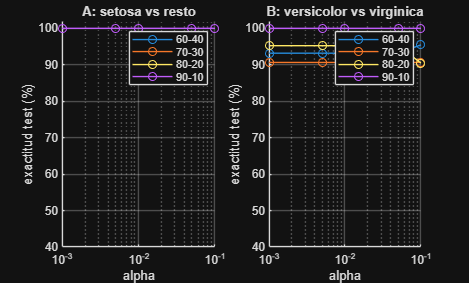

figure
for pr = 1:2
    subplot(1,2,pr); hold on
    for k = 1:4
        m = strcmp(R.Problema, problemas{pr}) & R.k == k;
        plot(R.Alpha(m), R.Exact_test(m), '-o', 'DisplayName', R.Particion{find(m,1)});
    end
    set(gca, 'XScale', 'log'); grid on; ylim([40 102]); legend
    xlabel('alpha'); ylabel('exactitud test (%)'); title(problemas{pr});
end

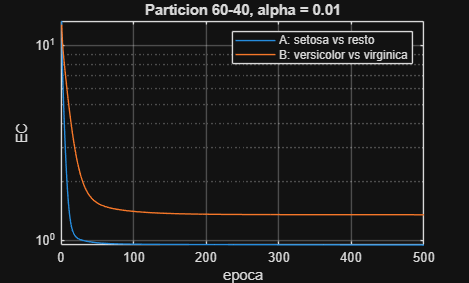


figure
semilogy(curva{1}); hold on; semilogy(curva{2}); grid on
xlabel('epoca'); ylabel('EC'); legend(problemas); title('Particion 60-40, alpha = 0.01')